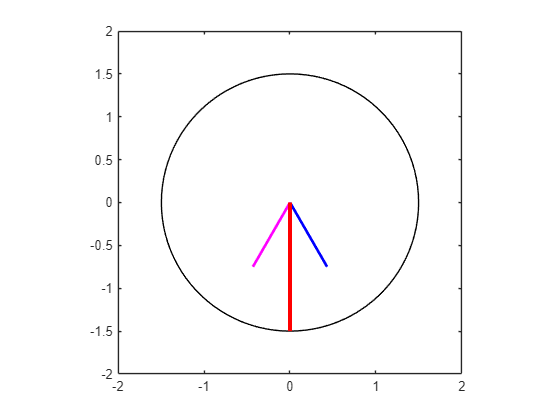

% M-file: mag_field.m
% M-file to calculate the net magnetic field produced
% by a three-phase stator.

% Set up the basic conditions
bmax = 1;            % Normalize bmax to 1
freq = 60;           % 60 Hz
w = 2*pi*freq;       % Angular velocity (rad/s)

% First, generate the three component magnetic fields
t = [0:1/6000:1/60];  % Time array

Baa = sin(w*t) .* (cos(0) + 1j*sin(0));
Ebb = sin(w*t - 2*pi/3) .* (cos(2*pi/3) + 1j*sin(2*pi/3));
Ecc = sin(w*t + 2*pi/3) .* (cos(-2*pi/3) + 1j*sin(-2*pi/3));

% Calculate Enet
Enet = Baa + Ebb + Ecc;

% Calculate a circle representing the expected maximum value of Enet
circle = 1.5 * (cos(w*t) + 1j*sin(w*t));

% Plot the magnitude and direction of the resulting magnetic fields
% Note that Baa is black, Ebb is blue, Ecc is magenta, and Enet is red.
for ii = 1:length(t)
    % Plot the reference circle
    plot(circle, 'k');
    hold on;

    % Plot the four magnetic fields
    plot([0 real(Baa(ii))], [0 imag(Baa(ii))], 'k', 'LineWidth', 2);
    plot([0 real(Ebb(ii))], [0 imag(Ebb(ii))], 'b', 'LineWidth', 2);
    plot([0 real(Ecc(ii))], [0 imag(Ecc(ii))], 'm', 'LineWidth', 2);
    plot([0 real(Enet(ii))], [0 imag(Enet(ii))], 'r', 'LineWidth', 3);

    axis square;
    axis([-2 2 -2 2]);
    drawnow;
    hold off;
end